# Exercises 7.1

1. The nodal displacements at the three nodes of a 1D element are shown in the table. Find the displacement atξ= 0.5.Explain why the result of the interpolation is negative if all nodal values are positive?

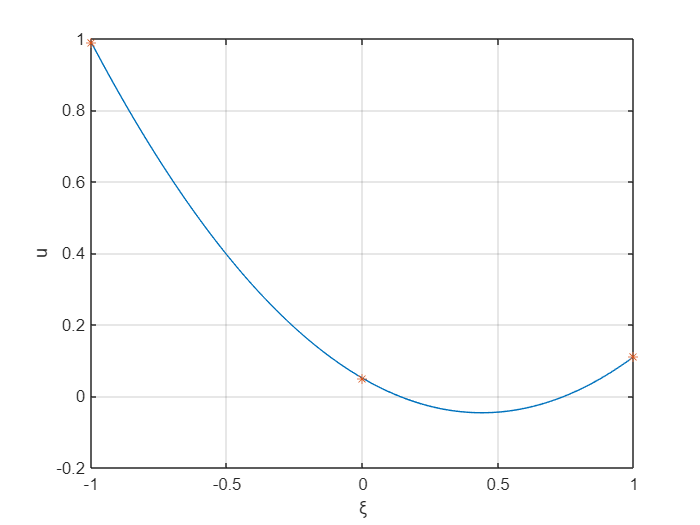

n = 101;
xi = linspace (-1, 1, n);      
u = [
0.99,                  % x1 = -1
0.11,                  % x1 = 1
0.05];                 % x1 = 0
for num = 1:n
    N = shape_form_1d(xi(num));
    U(num,1) = N * u;
end
figure
plot(xi,U,[-1,1,0],u,'*')
grid;
xlabel ("ξ");
ylabel ("u");

function N = shape_form_1d(xi)
N = [
1/2*xi^2 - 1/2*xi;     % N1
1/2*xi^2 + 1/2*xi;     % N2
1 - xi^2               % N3
]';                   
end